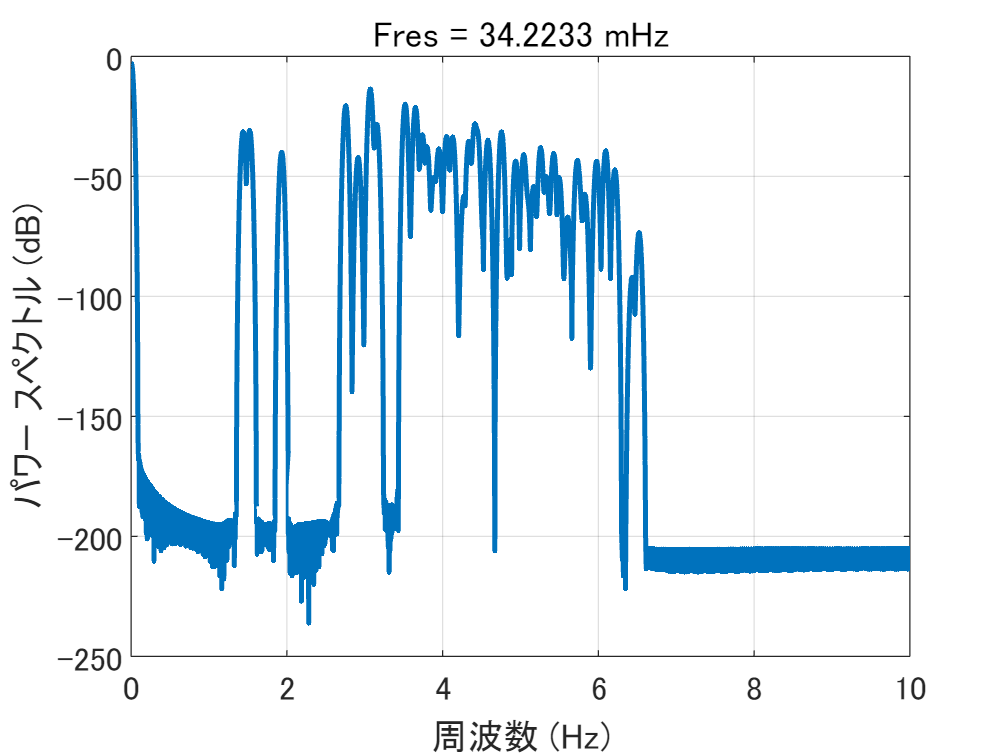

pspectrum(permute(simulation.cos.phi(48,1,:),[3,1,2]),0:simulation.param.dt:simulation.param.dt*(simulation.param.Nt-1))

f = sqrt(simulation.cos.sigma(3:5,1,1)*simulation.cos.param.kappa)/2/pi

f =     1.4239
    1.5060
    1.9019


T = 1/(f(2)-f(1))

T = 12.1779

kT = T/simulation.param.dt

kT = 243.5580

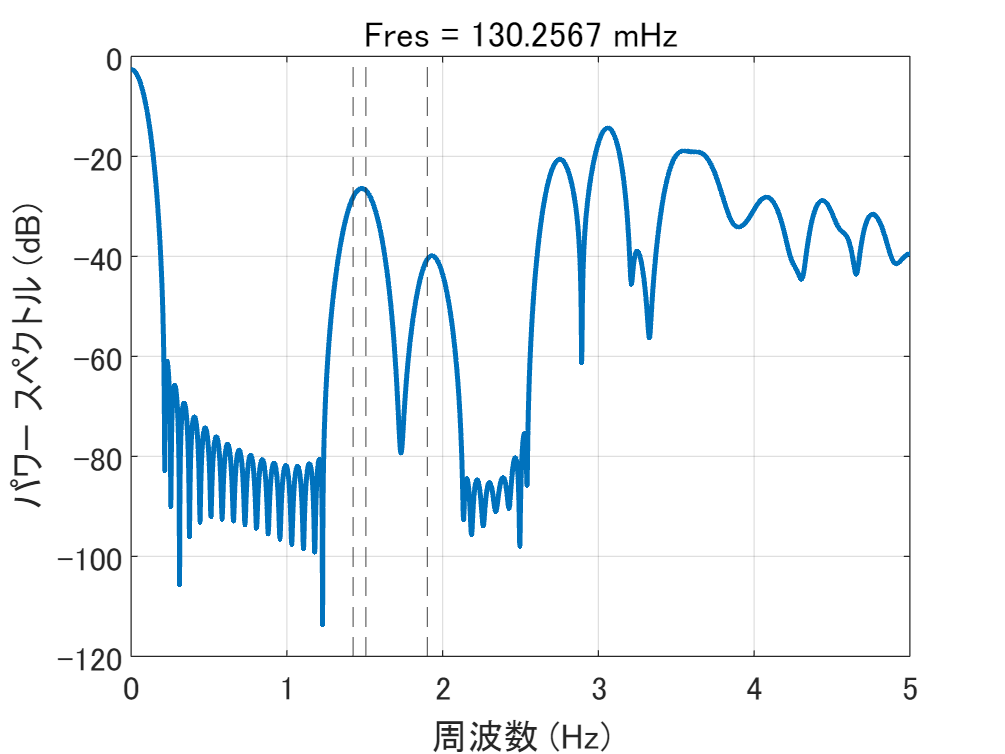

N = 256;
t_start = 1;
leakage = 0.8;
pspectrum(permute(simulation.cos.phi(48,1,t_start:t_start+N-1),[3,1,2]),0:simulation.param.dt:simulation.param.dt*(N-1),'Leakage',leakage)
xline(f(1:3),'--')
xlim([0 5])

diff_f = f(2)-f(1)

diff_f = 0.0821